# RCS of Satellite

Create satellite surface from an STL file.

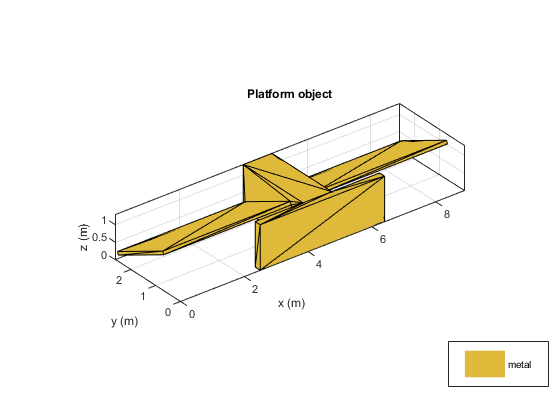

p = platform;
p.FileName = ['STK/sentinel1a.stl']; 
p.Units = 'm';
freq = 450e6;
figure
show(p)

Mesh the platform with edge length of 0.5

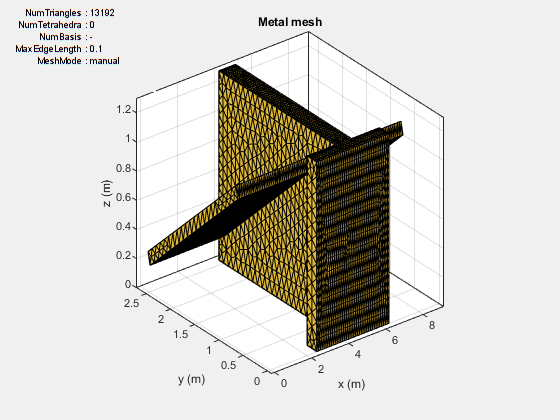

figure
mesh(p,'MaxEdgeLength', 0.1)

Sweep over the elevation with a vertically polarized E-field. Plot the RCS at 450 MHz in the azimuth plane.

az = 0:1:360;
el = 0;
figure 
rcs(p,freq,az,el)
[rcsval,az,el] = rcs(p,freq,az,el)
pow = db2pow(rcsval);
pow_avg = mean(pow);
RCSavg = mean(rcsval)
RCSavgp = pow2db(pow_avg)


*Copyright 2019 The MathWorks, Inc.*